% % Problem 2
% % 
% % defining parameters
n = 100; %n # random points.
L = 20;
rmin = .7; r1=70; rmax = sqrt(2*L^2); %rmax is the maximum distance two adjcent vertices
xyz = rand(3,1)*L;
 
x = [xyz(1) zeros(1,n-1)];  y = [xyz(2) zeros(1,n-1)];%initialize the random points
k = 1;
%b:
while k < n
    cen = rand(2,1)*L; %starting point(centers)
    cx = cen(1);        % x component
    cy = cen(2);        % y component
    for j = 1:n
        rm = rmax;
        rmax = sqrt((x(j)-cx)^2+(y(j)-cy)^2);
        rmax = min(rm,rmax);
    end
    if rmax > rmin
        k = k+1;
        x(k) = cx;
        y(k) = cy;
    end
    rmax = rmin*r1;
end

## from 2b we had...........

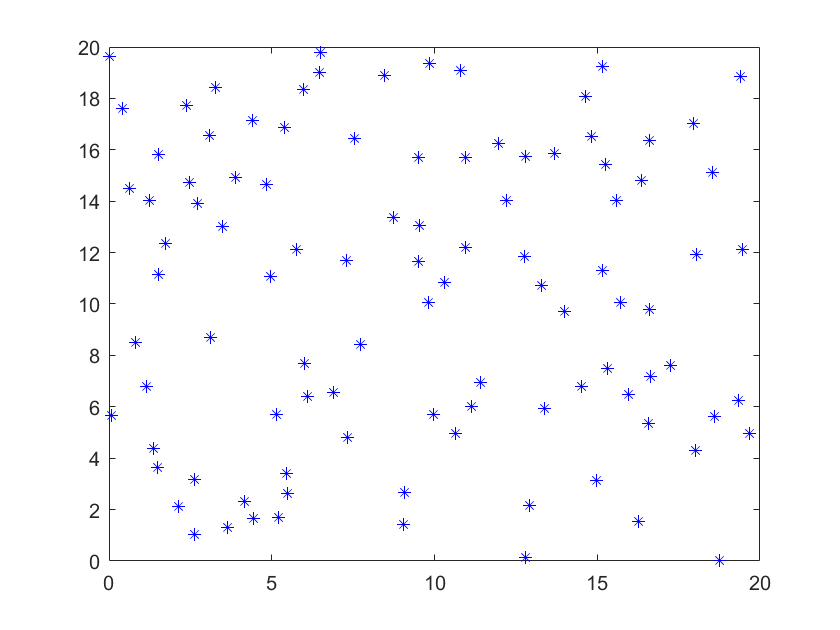

% x=[ 160.1671 366.9226 430.7894 540.1208 660.2771 508.7287 252.1787];
% y=[ 223.9615 259.5000 120.5769 245.5000 283.1923 472.7308 469.5000];
 plot(x,y,'b*')

5a: using MatLab inbuilt funntion (delaunayTriangulation() and triplot())


% figure(3)
% figure('Name','Inbuilt funtion')
% 
% DT = delaunayTriangulation(x',y');
% triplot(DT);
% hold on;
% plot(x,y,'r*')
% hold off

5b: D Elaunay Triangulation code

from $(x-h)^{2} + (y-k)^{2} -r^{2}=0$ generalized to $-ax -by +c = x^{2} +y^{2}$ we can solve for the unkwnon $a , b$ and $c$ given three distnct points.

 $a=2h$, $b=2k$ and $c= h^{2} +k^{2} -r^{2}$


cd1 = [];
ctrs1 = [];
for i = 1:length(x)-2
    for j = i+1:length(x)
        for k = j+1:length(x)
            A_mat = [ -x(i) -y(i) 1; -x(j) -y(j) 1; -x(k) -y(k) 1];
            b_vec = [ -(x(i)^2+y(i)^2); -(x(j)^2+y(j)^2); -(x(k)^2+y(k)^2)];
            coef = A_mat\b_vec;
            a = coef(1); b = coef(2); c = coef(3); 
            u1 = 0;
            for m = 1:length(x)
                if m == i || m == j || m == k
                    continue
                end
                C_equ = x(m)^2+y(m)^2-a*x(m)-b*y(m)+c;
                u1 = min(u1,C_equ);
            end
            if u1 >= 0
                 cd = [cd1; i j k ];
                 cd1=cd;
                 
                 ctrs = [ctrs1; a/2 b/2 ];
                 ctrs1=ctrs;
            end
        end
    end
end


## Triangulation from code


% figure(5)
% pos1 = [0.1 0.3 0.4 0.4];
% subplot('position',pos1)
% 
% plot(x,y,'r*')
% hold on;
% triplot(cd,x,y);
% 
% 
% hold off;
% pos2 = [0.6 0.3 0.4 0.4];
%  subplot('position',pos2)
% plot(x,y,'r*')
% hold on;
% 
% DT = delaunayTriangulation(x',y');
% triplot(DT);
% hold off
 

6a

from triangulation we find the internal triangles that share edges let t and tt be triangles that share edges 

taking two vertices from t at a time v_i and v_j are endpoints of the edges of triangles in tt

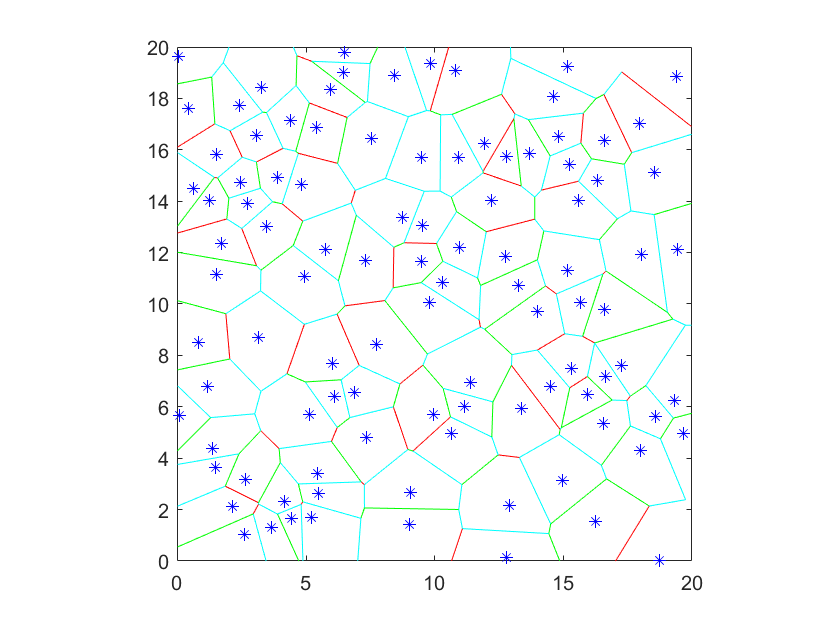

lc=length(cd); 
for t=1:lc
    v1=cd(t,1);v2=cd(t,2);v3=cd(t,3); %verteces of t
    for tt=t+1:lc
        u1=cd(tt,1);u2=cd(tt,2);u3=cd(tt,3);%verteces of tt
        if (v1==u1 || v1==u2 || v1==u3) && (v2 ==u1 || v2==u2 || v2==u3)
            vx=[ ctrs(t,1) ctrs(tt,1)]; %Internal edges
            vy=[ ctrs(t,2) ctrs(tt,2)];

            hold on
            plot(vx,vy,'r');
        
       
       elseif (v1==u1 || v1==u2 || v1==u3) && (v3==u1 || v3==u2 || v3==u3)
            vx=[ ctrs(t,1) ctrs(tt,1)]; %Internal edges
            vy=[ ctrs(t,2) ctrs(tt,2)];

            
            plot(vx,vy,'g');
             
        
        elseif (v2==u1 || v2==u2 || v2==u3) && (v3==u1 || v3==u2 || v3==u3)
            vx=[ctrs(t,1) ctrs(tt,1)]; %Internal edges
            vy=[ctrs(t,2) ctrs(tt,2)];

            
            plot(vx,vy,'c');
            axis equal
            xlim([0 L]); ylim([0 L])
        end
    end 
end

hold off

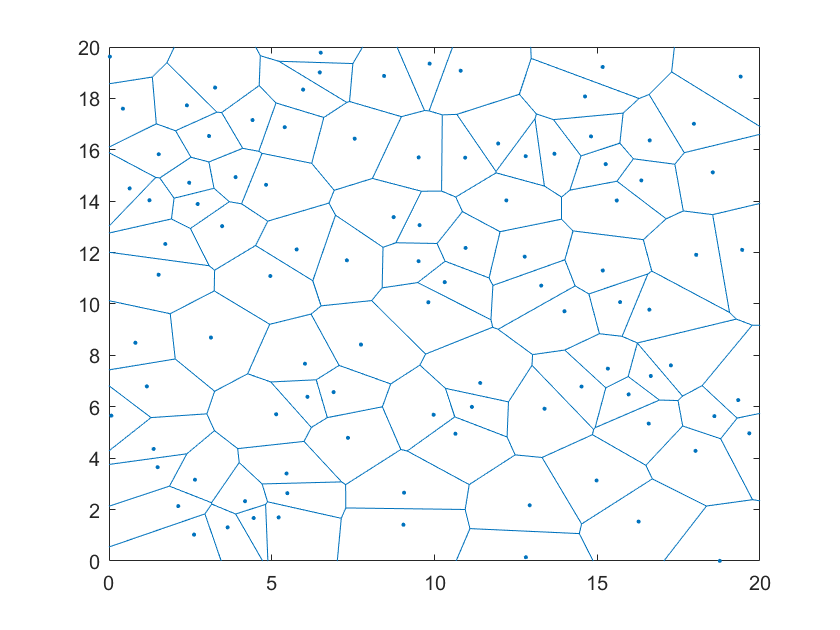

voronoi(x,y)